close all;
clear;
clc;
syms theta(t) theta_0 theta_t0
syms phi t
m = 1

m = 1

I = 1

I = 1

g= -9.8

g = -9.8000

l = 1

l = 1

C_f = 1

C_f = 1



eqn = diff(theta,2) == (g*l*m *sin(theta) + C_f * diff(theta,1))*I

$$eqn(t) = \frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)=\frac{\partial }{\partial t}\theta \left(t\right)-\frac{49\,\sin\left(\theta \left(t\right)\right)}{5}$$

theta_t = diff(theta,1)

$$theta\_t(t) = \frac{\partial }{\partial t}\theta \left(t\right)$$

cond = [theta(0)== pi/2,theta_t(0)==0]

$$cond = \left(\begin{array}{cc} \theta \left(0\right)=\frac{\pi }{2} & \left({\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)|}_{t=0}\right)=0 \end{array}\right)$$

eqn = diff(theta,2)*I +(g*l*m *theta - C_f * diff(theta,1))*I

$$eqn(t) = \frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)-\frac{\partial }{\partial t}\theta \left(t\right)-\frac{49\,\theta \left(t\right)}{5}$$

syms t s
syms theta(t) Theta
lap_eqn = laplace(eqn, t, s);

%eqn = diff(theta,2)*I +C_f *diff(theta) - g*l*m * theta
l_eqn = laplace(eqn)

$$l\_eqn = \theta \left(0\right)-s\,\mathrm{laplace}\left(\theta \left(t\right),t,s\right)-s\,\theta \left(0\right)-\left({\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)|}_{t=0}\right)+s^{2}\,\mathrm{laplace}\left(\theta \left(t\right),t,s\right)-\frac{49\,\mathrm{laplace}\left(\theta \left(t\right),t,s\right)}{5}$$

syms theta_s t s

subs(l_eqn, laplace(theta(t), t, s), Theta);
lap_eqn_subs = subs(l_eqn, laplace(theta(t), t, s), Theta)/Theta;
lap_eqn_subs

$$lap\_eqn\_subs = -\frac{\frac{49\,\Theta }{5}-\theta \left(0\right)+\Theta \,s+s\,\theta \left(0\right)+\left({\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)|}_{t=0}\right)-\Theta \,s^{2}}{\Theta }$$

s_tf = tf('s')


s_tf =
 
  s
 
Continuous-time transfer function.


lap_eqn_sub = subs(lap_eqn_subs,theta(0),0)

$$lap\_eqn\_sub = -\frac{\frac{49\,\Theta }{5}+\Theta \,s+\left({\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)|}_{t=0}\right)-\Theta \,s^{2}}{\Theta }$$


expand(1/lap_eqn_subs)

$$ans = -\frac{\Theta }{\frac{49\,\Theta }{5}-\theta \left(0\right)+\Theta \,s+s\,\theta \left(0\right)+\left({\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)|}_{t=0}\right)-\Theta \,s^{2}}$$


eqn_cancled = 1/(49/5- pi/2 + s_tf/10 + s_tf^2)


eqn_cancled =
 
          10
  ------------------
  10 s^2 + s + 82.29
 
Continuous-time transfer function.


G_s = eqn_cancled


G_s =
 
          10
  ------------------
  10 s^2 + s + 82.29
 
Continuous-time transfer function.


eqn_cancled = eqn_cancled/(1+eqn_cancled)


eqn_cancled =
 
             100 s^2 + 10 s + 822.9
  --------------------------------------------
  100 s^4 + 20 s^3 + 1747 s^2 + 174.6 s + 7595
 
Continuous-time transfer function.


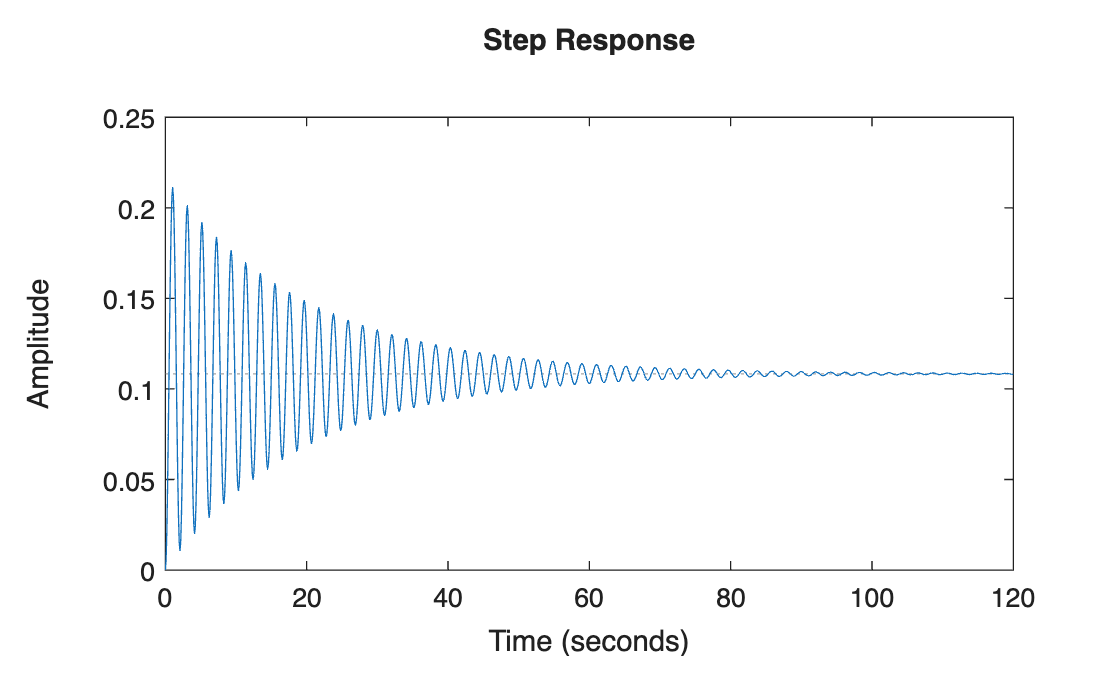

step(eqn_cancled)

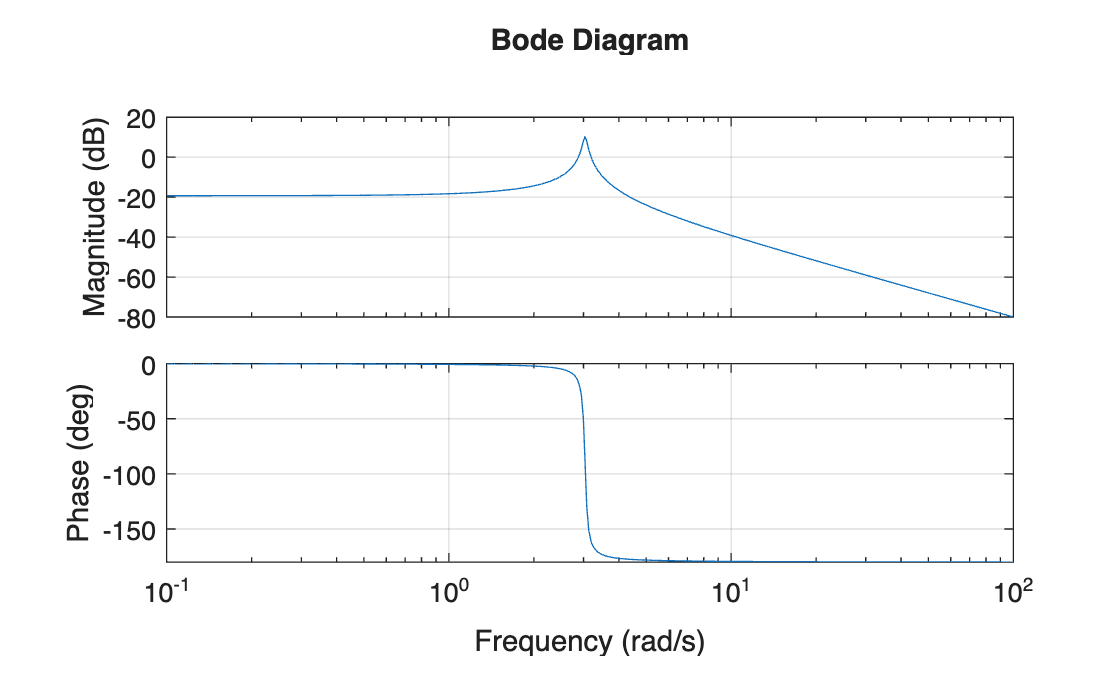

bode(eqn_cancled)
grid on


s = tf('s')


s =
 
  s
 
Continuous-time transfer function.


C_s = 160*((s+2.5)*(s+1.4))/((s+13)*(s+0.9))


C_s =
 
  160 s^2 + 624 s + 560
  ---------------------
   s^2 + 13.9 s + 11.7
 
Continuous-time transfer function.


%controlSystemDesigner(C_s)


L_s = C_s*G_s


L_s =
 
            1600 s^2 + 6240 s + 5600
  ---------------------------------------------
  10 s^4 + 140 s^3 + 213.2 s^2 + 1156 s + 962.8
 
Continuous-time transfer function.


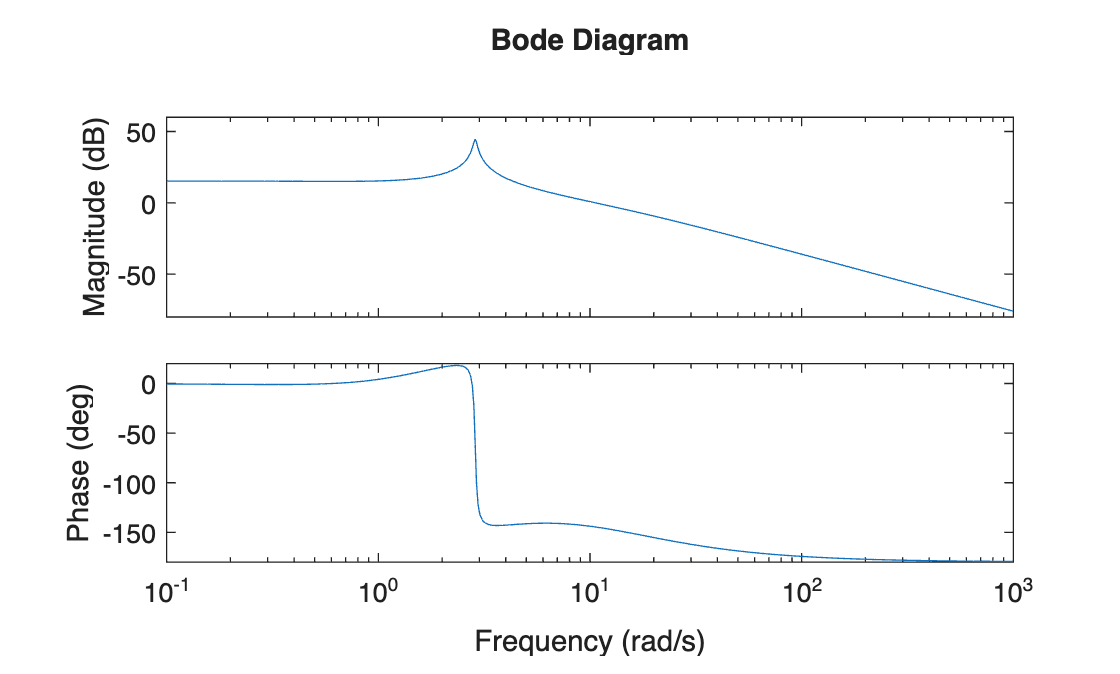

bode (L_s)

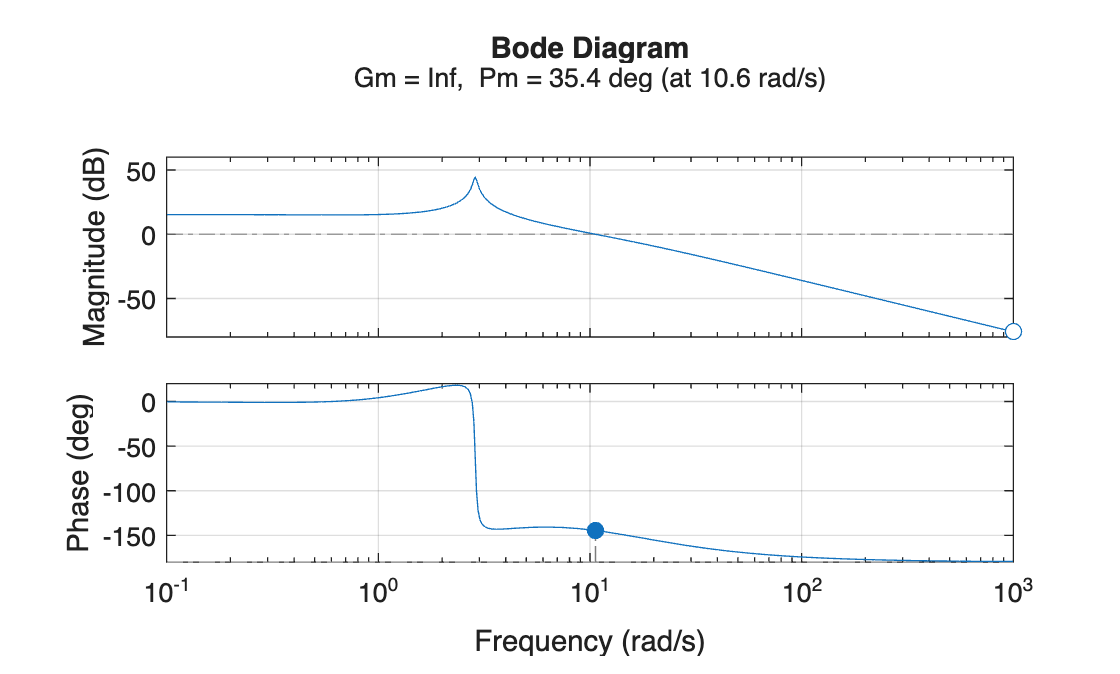

margin(L_s)
grid on

unity_feedback = L_s/(1+L_s) %(1-L_s)


unity_feedback =
 
              16000 s^6 + 286400 s^5 + 1.271e06 s^4 + 3.963e06 s^3 + 9.945e06 s^2 + 1.248e07 s + 5.392e06
  --------------------------------------------------------------------------------------------------------------------
  100 s^8 + 2800 s^7 + 3.986e04 s^6 + 3.692e05 s^5 + 1.659e06 s^4 + 4.726e06 s^3 + 1.169e07 s^2 + 1.47e07 s + 6.319e06
 
Continuous-time transfer function.


poles = pole(unity_feedback)

poles =  -13.0000 + 0.0000i
  -4.3230 +10.5495i
  -4.3230 -10.5495i
  -4.1320 + 0.0000i
  -0.0500 + 2.8682i
  -0.0500 - 2.8682i
  -1.2220 + 0.0000i
  -0.9000 + 0.0000i


zeros = zero(unity_feedback)

zeros =  -13.0000 + 0.0000i
  -0.0500 + 2.8682i
  -0.0500 - 2.8682i
  -2.5000 + 0.0000i
  -1.4000 + 0.0000i
  -0.9000 + 0.0000i


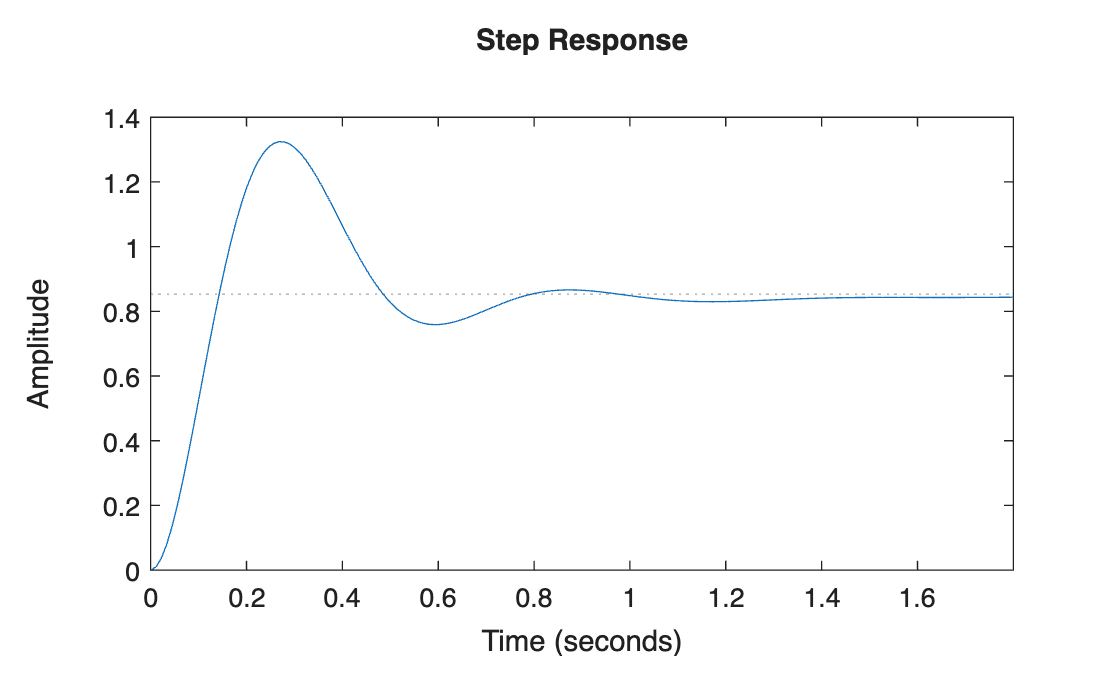


step(unity_feedback)

stepinfo(unity_feedback)

ans = struct with fields:
         RiseTime: 0.0966
    TransientTime: 1.3124
     SettlingTime: 1.3124
      SettlingMin: 0.7588
      SettlingMax: 1.3244
        Overshoot: 55.2054
       Undershoot: 0
             Peak: 1.3244
         PeakTime: 0.2675


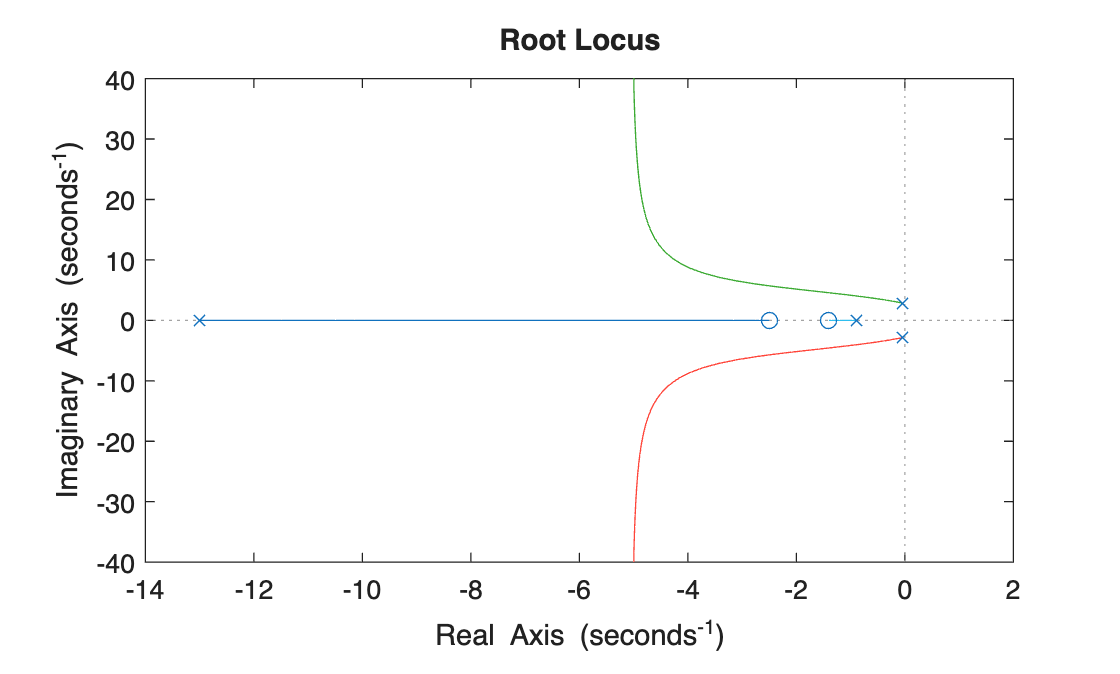

rlocus(L_s) %rlocus(unity_feedback)

zpk(unity_feedback)


ans =
 
            160 (s+13) (s+2.5) (s+1.4) (s+0.9) (s^2 + 0.1s + 8.229)
  ----------------------------------------------------------------------------
  (s+13) (s+4.132) (s+1.222) (s+0.9) (s^2 + 0.1s + 8.229) (s^2 + 8.646s + 130)
 
Continuous-time zero/pole/gain model.
